# 自由空间路径损耗模型

#### 对数距离路径损耗模型

自由空间传播模型用于预测LOS环境，常用于卫星通信。根据Friis公式：$P_r(d)=\frac{P_tG_tG_r\lambda^2}{(4\pi)^2d^2L}$

d为距离，L为系统总体衰减或损耗通常>1。假设系统硬件没有损耗，L=1，则接收功率随距离d指数衰减，即：


$$PL_F(d)[dB]=10log_{10}(\frac{P_t}{P_r}) = -10log_{10}(\frac{G_tG_r\lambda^2}{(4\pi)^2d^2})$$


当没有天线增益时，$G_t=G_r=1$，则简化为：


$$PL_F(d)[dB]=10log_{10}(\frac{P_t}{P_r}) = 20log_{10}(\frac{4\pi d}{\lambda})$$


#### 对数距离路径损耗模型

引入随环境改变的路径损耗指数n修正自由空间路径损耗模型即对数距离路径损耗模型：


$$PL_{LD}(d)[dB]=PL_{F}(d_0)+10nlog_{10}(\frac{d}{d_0})$$


n变化范围2~6，n=2是自由空间的情况，当障碍物增多，n变大。

#### 对数正态阴影模型

周围环境随接收机实际位置不同而改变，即使距离相同也会有不同路径损耗：


$$PL(d)[dB]=PL_F(d_0)+10nlog_{10}(\frac{d}{d_0})+X_{\sigma}$$


高斯随机变量均值为0，标准差为$\sigma$

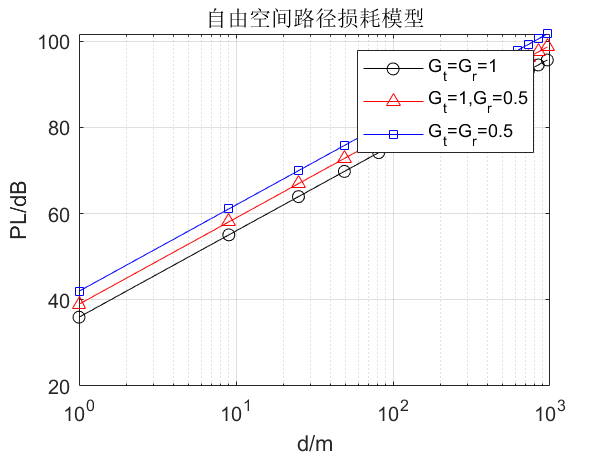

fc = 1.5e9;
d0 = 100;
sigma = 3;
d = [1:2:31].^2;
Gt = [1 1 0.5];
Gr = [1 0.5 0.5];
Exp = [2 3 6];
for k=1:3
    y_Free(k,:) = PL_free(fc,d,Gt(k),Gr(k));%调节天线增益
    y_logdist(k,:) = PL_longdist_or_norm(fc,d,d0,Exp(k));%调节路径损耗指数n
    y_lognorm(k,:) = PL_longdist_or_norm(fc,d,d0,Exp(1),sigma);
end

%第一张图，天线增益对自由空间损耗的影响
figure()
semilogx(d,y_Free(1,:),'k-o',d,y_Free(2,:),'r-^',d,y_Free(3,:),'b-s')
grid on;
title('自由空间路径损耗模型')
xlabel('d/m')
ylabel('PL/dB')
legend('G_t=G_r=1','G_t=1,G_r=0.5','G_t=G_r=0.5')

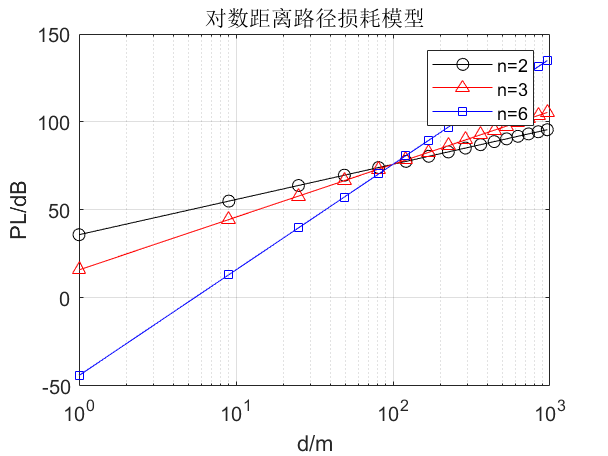


% 路径损耗指数n对自由空间损耗的影响
figure()
semilogx(d,y_logdist(1,:),'k-o',d,y_logdist(2,:),'r-^',d,y_logdist(3,:),'b-s')
grid on;
title('对数距离路径损耗模型')
xlabel('d/m')
ylabel('PL/dB')
legend('n=2','n=3','n=6')

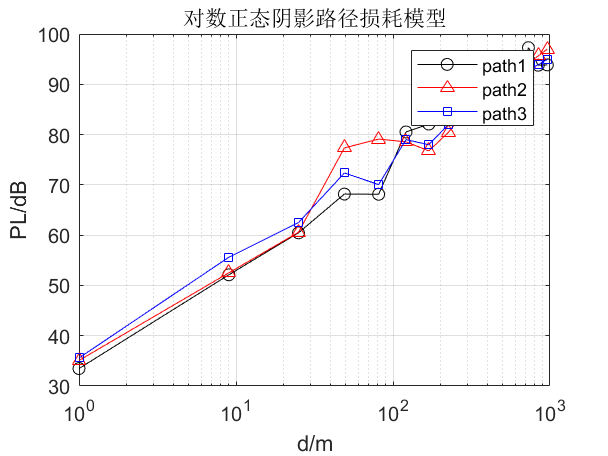


% 对数正态阴影路径损耗模型
figure()
semilogx(d,y_lognorm(1,:),'k-o',d,y_lognorm(2,:),'r-^',d,y_lognorm(3,:),'b-s')
grid on;
title('对数正态阴影路径损耗模型')
xlabel('d/m')
ylabel('PL/dB')
legend('path1','path2','path3')

function PL=PL_free(fc,d,Gt,Gr)
    lambda = 3e8/fc;
    tmp = lambda./(4*pi*d);
    if nargin>2,tmp = tmp*sqrt(Gt);end
    if nargin>3,tmp = tmp*sqrt(Gr);end
    PL = -20*log10(tmp);
end

function PL = PL_longdist_or_norm(fc,d,d0,n,sigma)
    lambda = physconst('l')/fc;
    PL = -20*log10(lambda/(4*pi*d0))+10*n*log10(d/d0);
    if nargin>4
        PL=PL+sigma*randn(size(d));
    end
end

